% Constant
e = 1.6 * 10^-19;
c = 3*10^8;

% Change Data here
lamda = [365 405 436 546 577];
lamda = lamda .* 10^-9;
v = c ./ lamda

v =            821917808219178           740740740740741           688073394495413           549450549450549           519930675909879


Ua = [1.74 1.41 1.16 0.72 0.56];

% lx
% 577nm
l = [1 0.75 0.5 0.25];
Ual = [42.60 35.40 21.30 8.47] .* 200 * 10^-7;

% lets do the fit
v = v';
Ua = Ua';
ftpx = fittype('poly1');
fx = fit(v, Ua, ftpx)

fx =      Linear model Poly1:
     fx(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   3.793e-15  (3.315e-15, 4.271e-15)
       p2 =      -1.401  (-1.723, -1.078)


l = l';
Ual = Ual';
fxl = fit(l, Ual, ftpx);

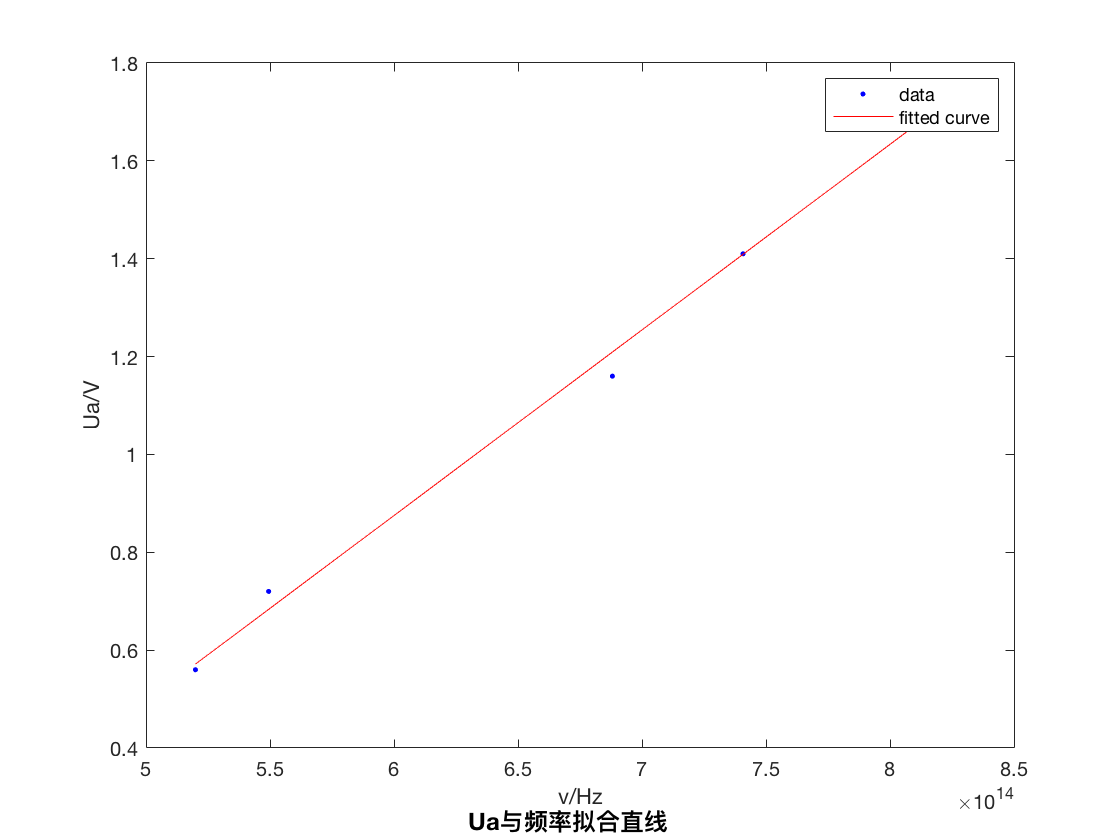

% Plot
plot(fx, v, Ua)
text(6.3*10^14, 0.25, 'Ua与频率拟合直线', 'FontWeight','bold', 'FontSize',12)
ylabel('Ua/V')
xlabel('v/Hz')

h = fx.p1 * e

h =       6.06886046652697e-34


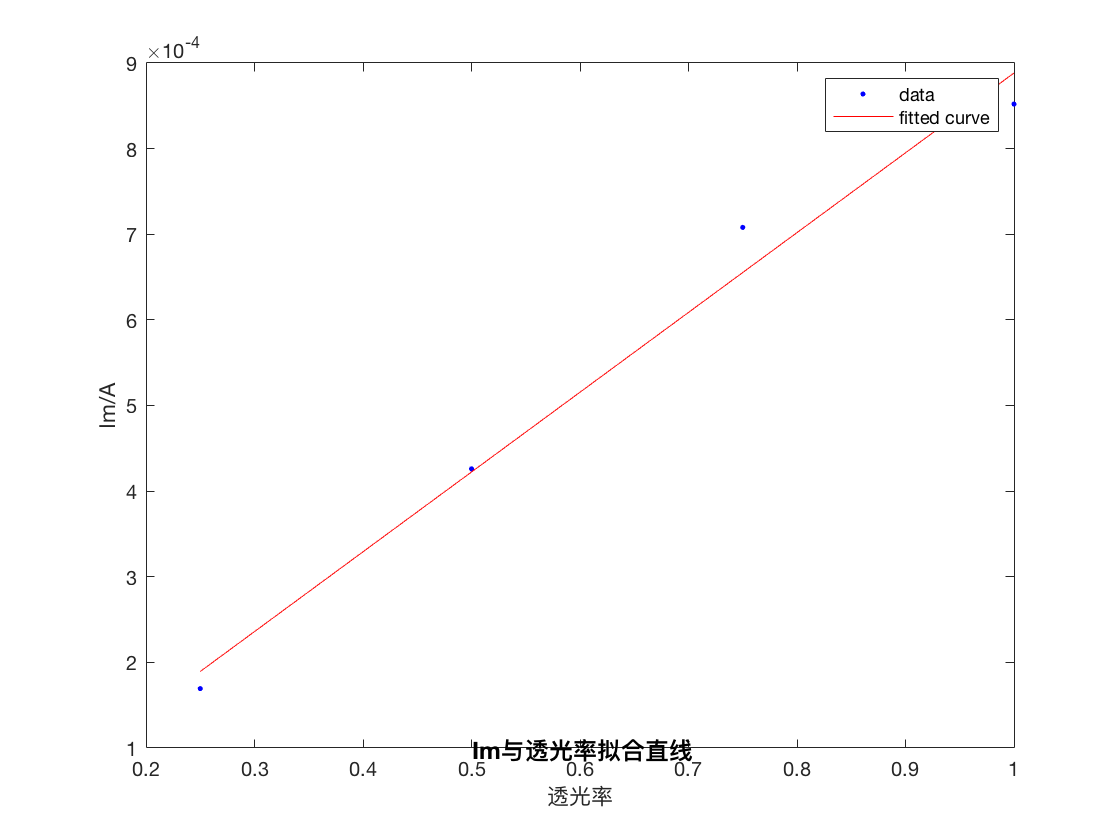


plot(fxl, l, Ual)
text(0.5, 0.98*10^-4, 'Im与透光率拟合直线 ', 'FontWeight','bold', 'FontSize',12)
xlabel('透光率')
ylabel('Im/A')

w = h*v(1) - e*Ua(1)

w =       2.20410449303587e-19


w/h

ans =            363182595018074
